clear all
N=25;
L=40;
R=5;

%**********************************
%***** Top / bottom triangles 
%**********************************
NH = N*cos(pi/6);
NL = 0.5*N;
LH = cos(pi/6)*L;
LL= 0.5*L;
empty_counter = 0;

% Top:
n=1;
for i=1:N; % for loop creating the first square
    for j=1:N;
        x(n) = i*(LL/N);
        y(n) = j*(LH/N);
        z(n) = R;
        area_top(n) = (0.5*LL*LH)/(0.5*N^2); % area assigned to every point. Please note, that this is a fairly crude estimation, that becomes increasingly more inaccurate with fewer points.
        x_norm_top(n) = 0;
        y_norm_top(n) = 0;
        z_norm_top(n) = 1;
        if y(n)>tan(pi/3)*x(n) % removes positions outside of the triangle
            x(n) = NaN;
            y(n) = NaN;
            z(n) = NaN;
            area_top(n) = NaN;
            x_norm_top(n) = NaN;
            y_norm_top(n) = NaN;
            z_norm_top(n) = NaN;
            n=n+1;
        else
            n=n+1;
            empty_counter=empty_counter+1;
        end
    end
end
for i=1:N; % for loop creating the second square
    for j=1:N;
        x(n) = LL+i*(LL/N);
        y(n) = j*(LH/N);
        z(n) = R;
        area_top(n) = (0.5*LL*LH)/(0.5*N^2);
        x_norm_top(n) = 0;
        y_norm_top(n) = 0;
        z_norm_top(n) = 1;
        if y(n)>tan(pi/3)*(LL-(x(n)-LL))
            x(n) = NaN;
            y(n) = NaN;
            z(n) = NaN;
            area_top(n) = NaN;
            x_norm_top(n) = NaN;
            y_norm_top(n) = NaN;
            z_norm_top(n) = NaN;
            n=n+1;
        else
            n=n+1;
            empty_counter=empty_counter+1;
        end
    end
end
S_top = [x;y;z]; % surface matrix
norm_top = [x_norm_top;y_norm_top;z_norm_top];
clear x y z
% Bottom:
n=1;
for i=1:N;
    for j=1:N;
        x(n) = i*(LL/N);
        y(n) = j*(LH/N);
        z(n) = -R;
        area_bottom(n) = (0.5*LL*LH)/(0.5*N^2);
        x_norm_bottom(n) = 0;
        y_norm_bottom(n) = 0;
        z_norm_bottom(n) = -1;
        if y(n)>tan(pi/3)*x(n)
            x(n) = NaN;
            y(n) = NaN;
            z(n) = NaN;
            area_bottom(n) = NaN;
            x_norm_bottom(n) = NaN;
            y_norm_bottom(n) = NaN;
            z_norm_bottom(n) = NaN;
            n=n+1;
        else
            n=n+1;
            empty_counter=empty_counter+1;
        end
    end
end
for i=1:N;
    for j=1:N;
        x(n) = LL+i*(LL/N);
        y(n) = j*(LH/N);
        z(n) = -R;
        area_bottom(n) = (0.5*LL*LH)/(0.5*N^2);
        x_norm_bottom(n) = 0;
        y_norm_bottom(n) = 0;
        z_norm_bottom(n) = -1;
        if y(n)>tan(pi/3)*(LL-(x(n)-LL))
            x(n) = NaN;
            y(n) = NaN;
            z(n) = NaN;
            area_bottom(n) = NaN;
            x_norm_bottom(n) = NaN;
            y_norm_bottom(n) = NaN;
            z_norm_bottom(n) = NaN;
            n=n+1;
        else
            n=n+1;
            empty_counter=empty_counter+1;
        end
    end
end
S_bottom= [x;y;z];
norm_bottom = [x_norm_bottom;y_norm_bottom;z_norm_bottom];
clear x y z

%**********************************
%***** Cylindrical sides
%**********************************
L_cyl = LL;
N_phi = N;
N_cyl_z = (N*N_phi)/(pi*R);

% Side 1:
n=1;
for p_cyl_z=1:N_cyl_z
    for p_cyl_r=1:(N_phi*0.5)
        phi=((2*pi)/N_phi)*(p_cyl_r-0.5);    
        z(n)=R*cos(phi);
        y(n)=R*sin(phi);
        x(n) = -L_cyl+(L_cyl/N_cyl_z)+(2*L_cyl/N_cyl_z)*((-1/2)+p_cyl_z);
        y_norm_cyl(n)=sin(phi);
        z_norm_cyl(n)=cos(phi);
        x_norm_cyl(n)=0;
        area_cyl_1(n) =(2*pi*R*L)/(N_phi*N_cyl_z); % Also increasingly inaccurate with fewer points.
        n=n+1;
    end
end
S_cyl_1 = [x;y;z];
norm_cyl_1 = [x_norm_cyl;y_norm_cyl;z_norm_cyl];
% 60 degree transformation
angle = 1/3; % Divided by pi, since cospi/sinpi is used.
S_cyl_1 = [cospi(angle) -sinpi(angle) 0; sinpi(angle) cospi(angle) 0; 0 0 1]*[S_cyl_1] + [LL*0.5;0.5*LH;0];
norm_cyl_1 = [cospi(angle) -sinpi(angle) 0; sinpi(angle) cospi(angle) 0; 0 0 1]*[norm_cyl_1];
clear x y z

% Side 2:
n = 1;
for p_cyl_z=1:N_cyl_z
    for p_cyl_r=1:(N_phi*0.5)
        phi=((2*pi)/N_phi)*(p_cyl_r-0.5);    
        z(n)=R*cos(phi);
        y(n)=R*sin(phi);
        x(n) = -L_cyl+(L_cyl/N_cyl_z)+(2*L_cyl/N_cyl_z)*((-1/2)+p_cyl_z);
        y_norm_cyl(n)=sin(phi);
        z_norm_cyl(n)=cos(phi);
        x_norm_cyl(n)=0;
        area_cyl_2(n) =(2*pi*R*L)/(N_phi*N_cyl_z);
        n=n+1;
    end
end
S_cyl_2 = [x;y;z];
norm_cyl_2 = [x_norm_cyl;y_norm_cyl;z_norm_cyl];
% 300 degree transformation
angle = 5/3;
S_cyl_2 = [cospi(angle) -sinpi(angle) 0; sinpi(angle) cospi(angle) 0; 0 0 1]*[S_cyl_2]+[LL*1.5;LH*0.5;0];
norm_cyl_2 = [cospi(angle) -sinpi(angle) 0; sinpi(angle) cospi(angle) 0; 0 0 1]*[norm_cyl_2];
clear x y z

% Side 3:
n = 1;
for p_cyl_z=1:N_cyl_z
    for p_cyl_r=1:(N_phi*0.5)
        phi=((2*pi)/N_phi)*(p_cyl_r-0.5);    
        z(n)=R*cos(phi);
        y(n)=R*sin(phi);
        x(n) = -L_cyl+(L_cyl/N_cyl_z)+(2*L_cyl/N_cyl_z)*((-1/2)+p_cyl_z);
        y_norm_cyl(n)=sin(phi);
        z_norm_cyl(n)=cos(phi);
        x_norm_cyl(n)=0;
        area_cyl_3(n) = (2*pi*R*L)/(N_phi*N_cyl_z);
        n=n+1;
    end
end
S_cyl_3 = [x;y;z];
norm_cyl_3 = [x_norm_cyl;y_norm_cyl;z_norm_cyl];
% 180 degree transformation
angle = 1;
S_cyl_3 = [cospi(angle) -sinpi(angle) 0; sinpi(angle) cospi(angle) 0; 0 0 1]*[S_cyl_3] + [LL;0.3;0];
norm_cyl_3 = [cospi(angle) -sinpi(angle) 0; sinpi(angle) cospi(angle) 0; 0 0 1]*[norm_cyl_3];
clear x y z

%**********************************
%***** Spherical corners
%**********************************
N_phi = N;
N_theta = N_phi*0.5;

% Corner 1 (top)
n = 1;
for i_theta = 1:N_theta
    for i_phi = 1:N_phi/3
        phi_i = (i_phi-0.5)*((2*pi)/(N_phi));
        theta_i = (i_theta-0.5)*((pi)/N_theta);
        area_corner_1(n) = ((2*pi*(R^2))/(N_phi))*(cos(theta_i-(pi)/(2*N_theta))-cos(theta_i+(pi)/(2*N_theta))); % Also increasingly inaccurate with fewer points, but not as large of an error.
        x(n)= sin(theta_i)*cos(phi_i);
        y(n)= sin(theta_i)*sin(phi_i);
        z(n)= cos(theta_i);
        n=n+1;
    end
end
S_corner_1 = R.*[x;y;z];
% 30 degree transformation
angle = 1/6;
S_corner_1 = [cospi(angle) -sinpi(angle) 0; sinpi(angle) cospi(angle) 0;0 0 1]*[S_corner_1]+[LL;LH-0.6;0];
norm_corner_1 = [S_corner_1(1,:)-LL;S_corner_1(2,:)-LH;S_corner_1(3,:)]./R;
clear x y z

% Corner 2 (left)
n = 1;
for i_theta = 1:N_theta
    for i_phi = 1:N_phi/3
        phi_i = (i_phi-0.5)*((2*pi)/(N_phi));
        theta_i = (i_theta-0.5)*((pi)/N_theta);
        area_corner_2(n) = ((2*pi*(R^2))/(N_phi))*(cos(theta_i-(pi)/(2*N_theta))-cos(theta_i+(pi)/(2*N_theta)));
        x(n)= sin(theta_i)*cos(phi_i);
        y(n)= sin(theta_i)*sin(phi_i);
        z(n)= cos(theta_i);
        n=n+1;
    end
end
S_corner_2 = R.*[x;y;z];
% 150 degree transformation
angle = 5/6;
S_corner_2 = [cospi(angle) -sinpi(angle) 0; sinpi(angle) cospi(angle) 0;0 0 1]*[S_corner_2]+[0.3;0.3;0];
norm_corner_2 = [S_corner_2(1,:)-0.3;S_corner_2(2,:)-0.3;S_corner_2(3,:)]./R;
clear x y z

% Corner 3 (right)
n = 1;
for i_theta = 1:N_theta
    for i_phi = 1:N_phi/3
        phi_i = (i_phi-0.5)*((2*pi)/(N_phi));
        theta_i = (i_theta-0.5)*((pi)/N_theta);
        area_corner_3(n) = ((2*pi*(R^2))/(N_phi))*(cos(theta_i-(pi)/(2*N_theta))-cos(theta_i+(pi)/(2*N_theta)));
        x(n)= sin(theta_i)*cos(phi_i);
        y(n)= sin(theta_i)*sin(phi_i);
        z(n)= cos(theta_i);
        n=n+1;
    end
end
S_corner_3 = R.*[x;y;z];
% 270 degree transformation
angle = 3/2;
S_corner_3 = [cospi(angle) -sinpi(angle) 0; sinpi(angle) cospi(angle) 0;0 0 1]*[S_corner_3]+[L-0.3;0.3;0];
norm_corner_3 = [S_corner_3(1,:)-L+0.3;S_corner_3(2,:)-0.3;S_corner_3(3,:)]./R;
clear x y z

%**********************************
%***** Final function
%**********************************
S = [S_top S_bottom S_cyl_1 S_cyl_2 S_cyl_3 S_corner_1 S_corner_2 S_corner_3];
norm = [norm_top norm_bottom norm_cyl_1 norm_cyl_2 norm_cyl_3 norm_corner_1 norm_corner_2 norm_corner_3];
area = [area_top area_bottom area_cyl_1 area_cyl_2 area_cyl_3 area_corner_1 area_corner_2 area_corner_3];

F = [S;area;norm];
without_NaN = rmmissing(transpose(F));
F = transpose(without_NaN); % Function describing the entire model.
area = F(4,:);

% Here, the prism can be rotated around the z-axis by any angle.
angle = 2;
F = [cospi(angle) -sinpi(angle) 0 0 0 0 0;sinpi(angle) cospi(angle) 0 0 0 0 0;0 0 1 0 0 0 0;0 0 0 1 0 0 0;0 0 0 0 cospi(angle) -sinpi(angle) 0; 0 0 0 0 sinpi(angle) cospi(angle) 0;0 0 0 0 0 0 1]*F;

N = length(F)

N = 2848

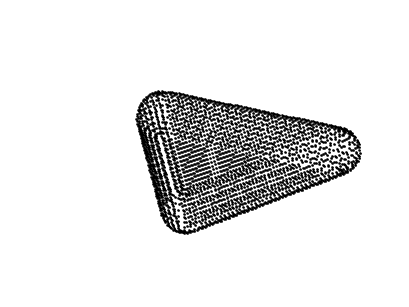

plot3(S(1,:),S(2,:),S(3,:),'k.')
hold on
set(gca,'visible','off') % Axis on/off
axis image
hold off

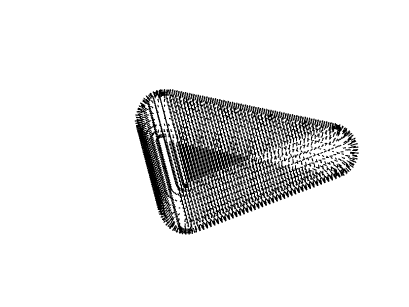


quiver3(F(1,:),F(2,:),F(3,:),F(5,:),F(6,:),F(7,:),'k')
hold on
set(gca,'visible','off') % Axis on/off
axis image
hold off